cd('C:\Users\PC\Desktop\3081\Content-based-Image-Retrieval')

%CIFAR100
% rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur','forest','hamster'};

%COREL80
rootFolder = 'CorelDB';
categories = {'art_antiques','obj_car','sc_sunset','wl_buttrfly','bld_sculpt'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 100;
[trainingSet, ~] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [256 256]); % can try without this
    sift = detectSIFTFeatures(I).selectStrongest(25);
    [features, sift_points] = extractFeatures(I, sift);
    featureSet = [featureSet features.'];
    ref = [ref repmat([i], 1, size(features,1))];
end


% construct LSH hash tables for featureSet
cd('vLSH')

% Tune hyperparameters
% Q = 144;  % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 10;   % # of tables
M = 25;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/10
	Projecting data...
	15538 buckets
	min / max size: 1 / 14
	mean / median: 1.087527e+00 / 1
Creating table 2/10
	Projecting data...
	14606 buckets
	min / max size: 1 / 24
	mean / median: 1.156922e+00 / 1
Creating table 3/10
	Projecting data...
	14961 buckets
	min / max size: 1 / 46
	mean / median: 1.129470e+00 / 1
Creating table 4/10
	Projecting data...
	14399 buckets
	min / max size: 1 / 30
	mean / median: 1.173554e+00 / 1
Creating table 5/10
	Projecting data...
	14903 buckets
	min / max size: 1 / 31
	mean / median: 1.133866e+00 / 1
Creating table 6/10
	Projecting data...
	14710 buckets
	min / max size: 1 / 47
	mean / median: 1.148742e+00 / 1
Creating table 7/10
	Projecting data...
	15169 buckets
	min / max size: 1 / 18
	mean / median: 1.113982e+00 / 1
Creating table 8/10
	Projecting data...
	14864 buckets
	min / max size: 1 / 48
	mean / median: 1.136841e+00 / 1
Creating table 9/10
	Projecting data...
	15426 buckets
	min / max size: 1 / 20
	mean / median: 1.095423e

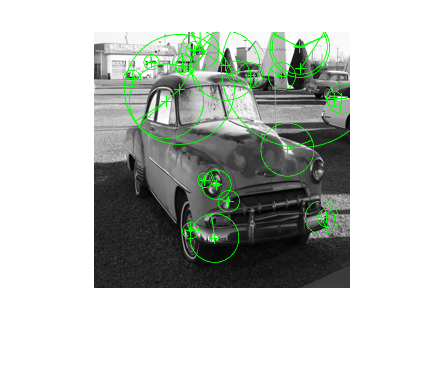

% query an input image
I = imread("car2.jpg");
I = imresize(im2gray(I), [256 256]);
figure, imshow(I); hold on;
sift = detectSIFTFeatures(I).selectStrongest(25);
[queryFeatures, valid_points] = extractFeatures(I, sift);
% plot(sift.selectStrongest(3))
plot(valid_points,'showOrientation',true);



% [idsSIMPLE, cand_sizeSIMPLE, binsFound_ratiosSIMPLE] = lshSearch(Qfeatures, X, lshStruct, K);
% [idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(featureSet(:, 1:Q), featureSet, lshStruct, K, T);
[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(queryFeatures.', featureSet, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.101473 seconds
Retrieving candidates from table 2
	-----> 0.094316 seconds
Retrieving candidates from table 3
	-----> 0.089921 seconds
Retrieving candidates from table 4
	-----> 0.094604 seconds
Retrieving candidates from table 5
	-----> 0.124577 seconds
Retrieving candidates from table 6
	-----> 0.096590 seconds
Retrieving candidates from table 7
	-----> 0.087362 seconds
Retrieving candidates from table 8
	-----> 0.098805 seconds
Retrieving candidates from table 9
	-----> 0.086611 seconds
Retrieving candidates from table 10
	-----> 0.083460 seconds
Removing duplicate candidates...
	-----> 0.001377 seconds
Performing knn search...
	-----> 0.001944 seconds
Calculating candidate sizes...
	-----> 0.011863 seconds


% convert the feature IDs into their original image IDs
oriImages = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          oriImages(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

% aggregate and weight the image features by their ranks 
uniqImageIds = unique(oriImages);
N = numel(uniqImageIds);
weights = zeros(N,1);
fib = zeros(1, K); fib(K-1) = 1;
for i = K-2:-1:1
   fib(i) = fib(i+1)+fib(i+2);
end

for k = 1 : N
%   count(k) = sum(sum(oriImages==uniqImageIds(k)));
%   exp(N-k+1)
%   count(k) = exp(N - k + 1) * sum(sum(oriImages == uniqImageIds(k)));
%   count(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));
  weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k)));
%   weights(k) = sum(fib * (oriImages == uniqImageIds(k)));
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


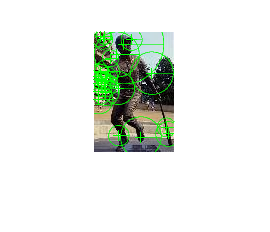

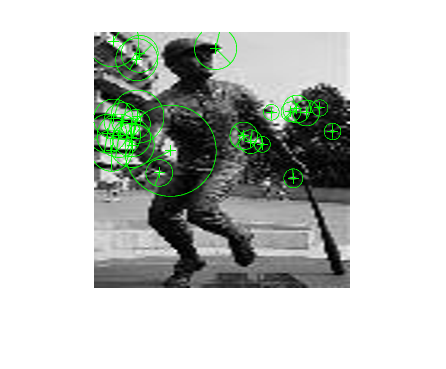

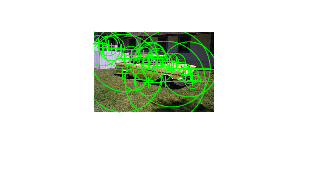

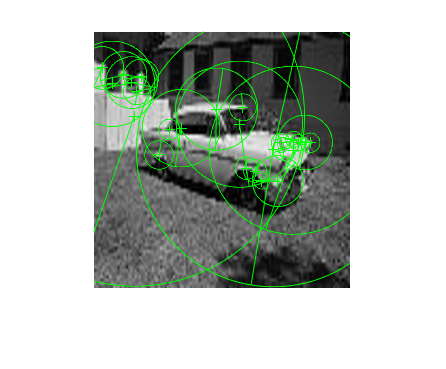

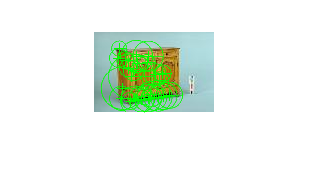

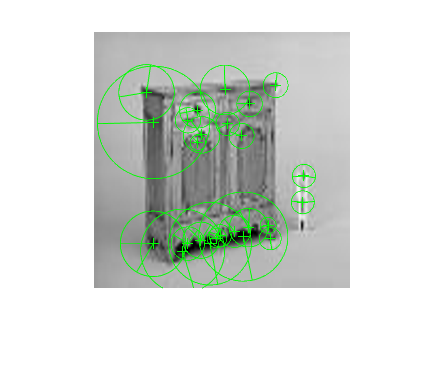

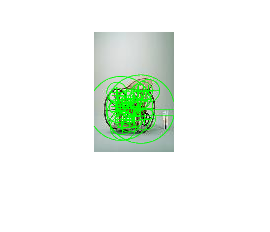

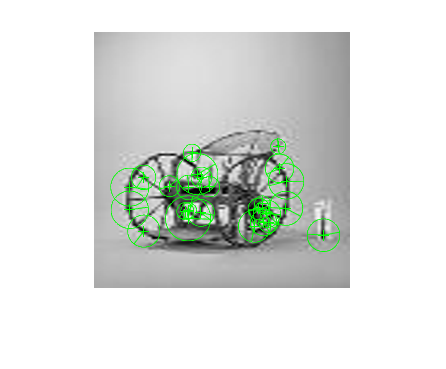

% display top 20 the matching images
for pic = 1 : min(20, length(ranks))
    if ranks(pic,2)>0
        I = readimage(trainingSet, ranks(pic, 2));
        figure, imshow(I); hold on;
        sift = detectSIFTFeatures(im2gray(I)).selectStrongest(25);
        % [queryFeatures, valid_points] = extractFeatures(I, sift);
        % plot(valid_points,'showOrientation',true);
        plot(sift,'showOrientation',true);
        I = imresize(im2gray(I), [256 256]);
        figure, imshow(I); hold on
        sift = detectSIFTFeatures(I).selectStrongest(25);
        [queryFeatures, valid_points] = extractFeatures(I, sift);
        plot(valid_points,'showOrientation',true);
    end
end